# Optimization design of rebar in a Single-Span concrete beam

This figure below shows the rebar design prototype considered for optimization design (search space). A maximum of three different rebar diameter sizes can be placed both at top reinforcement and bottom reinforcement.

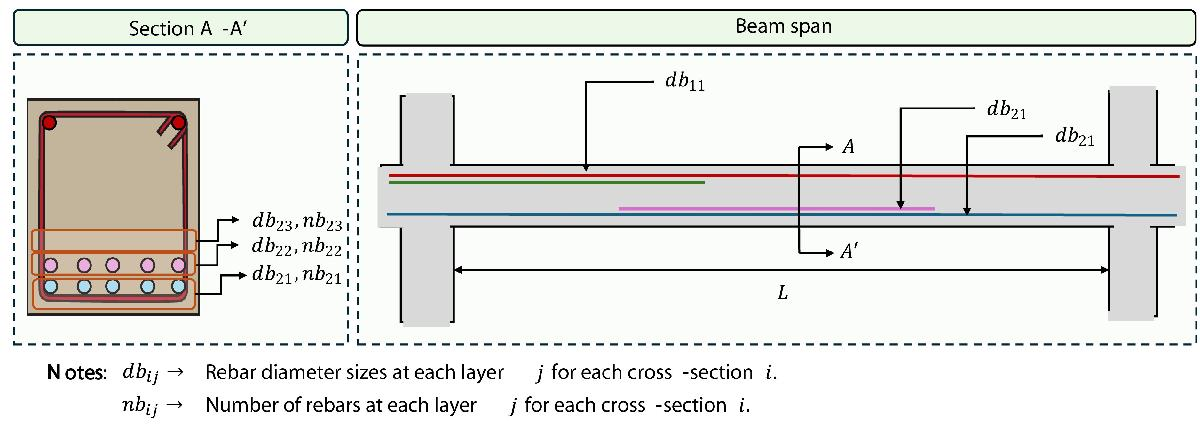

Note: This algorithm does not use any AI model nor enhancement but only plain Meta-heuristics (PSO in this case).

## Insert the folder path to store the rebar design results

Results will be stored as .csv files

directionData='C:\Users\lfver\OneDrive\Desktop\OneDrive\CALDRECUST\Software\Package\Visual_CALDRECUST\Design_Data\RebarBeams\';

% If results are to be saved, input saveResults=true
saveResults=true

saveResults = logical
   1


## Insert geometry of the beam element 

span=5000; % mm
b=300; % width (mm)
h=600; % height (mm)
        
hrec=50; % 
brec=50; % lateral concrete cover


## Insert material properties

### Concrete

fcu=35; % N/mm2

Ec=(3.46*sqrt(fcu)+3.21)*1e3; % N/mm2

### Steel reinforcement

fy=500; % Yield stress of steel reinforcement (N/mm2)
wac=7.85e-6; % unit volume weight of the reinforcing steel (Kg/mm3)

## Insert parameters for structural analysis with the FEM

### Create numerical model

% Discretization length
dL=100; % mm

% B.C.
supportsLoc=[0 span]; % location of supports (fixed-end supports)


### Distributed loads 

wrange=[0, span];
W=[25,30]; % Uniformly Distributed Load over the whole beam  N / mm
nspans=length(W(:,1));



## **Analysis is executed**

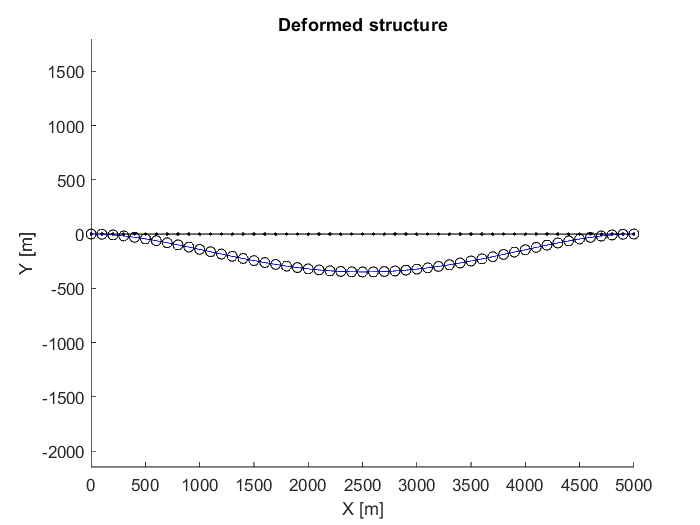

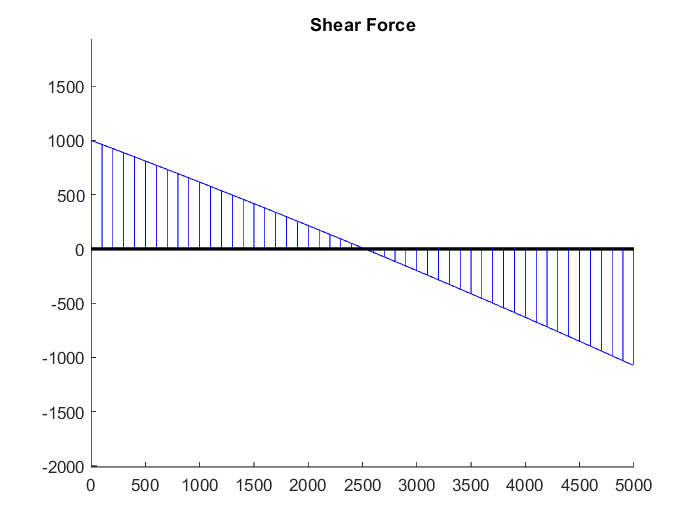

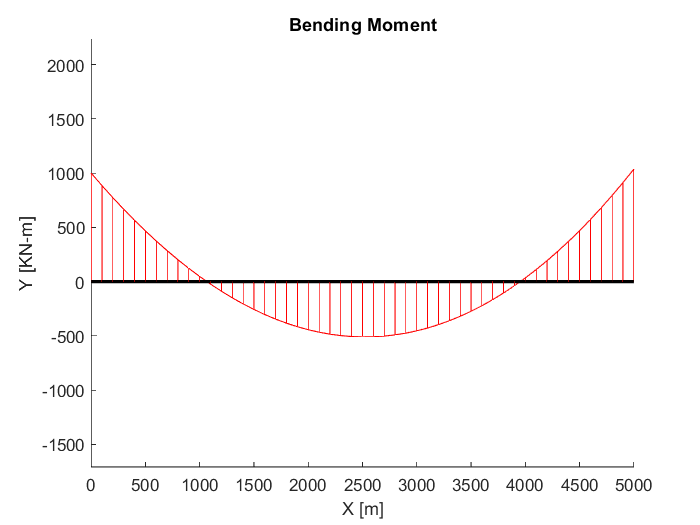


Ac=b*h;
Ic=b*h^3/12;
[R,U,V,M]=MSFSFEMBeams(span,Ac,Ic,Ec,supportsLoc,W,dL,wrange,1);

### Results from FEA are processed

The critical bending moments are extracted for the span (three main cross-sections left, mid and right). Based on the locations of these critical bending moments, the location of cuts is calcualted.


ne=zeros(1,nspans);
neSum=0;
load_conditions=[];
for i=1:nspans
    
    spanLengths(i)=supportsLoc(i+1)-supportsLoc(i);
    ne(i)=(supportsLoc(i+1)-supportsLoc(i))/dL;
    i1=neSum+1;
    Mleft=M(1,i1);
    
    neSum=neSum+ne(i);
    Mright=M(1,neSum);
    
    [Mmid,mp]=max(M(1,i1:neSum));
    load_conditions=[load_conditions;
                    i Mleft Mmid Mright]; %Kg-cm (flexure)
    
    %% Cut location ( local coordinates)
    cutxLocBeam(i,:)=cutLocationSSRecBeam(M(:,i1:neSum),dL);
end

## Rebar data

Aavialable commercial rebar diameters

% Format: [idx, diam (mm)]
rebarAvailable=[1 6;
                2 8;
                3 10;
                4 12;
                5 16;
                6 20;
                7 25;
                8 32;
                9 40]; % mm^2

Additional design parameters 

dvs=10; % default diameter size for shear links

%% Maximum and minimum reinforcement percentage area
pmin=0.003;
pmax=0.025;

% Max aggregate size (mm)
hagg=20;

## Optmization design of longitudinal reinforcement

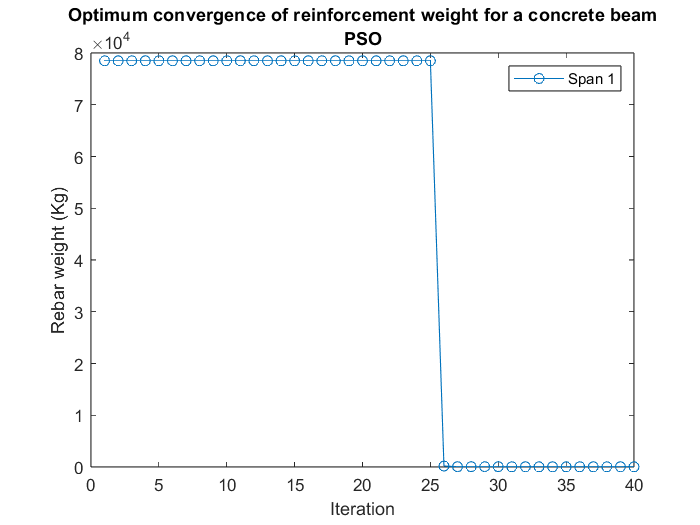

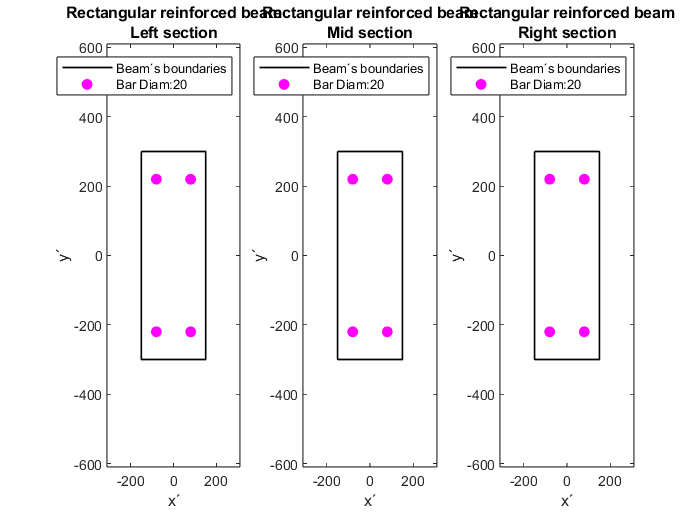

% Constructability weight factors (see documentation)
WUB=[0.6,0.7];
WND=[0.6];
WNB=[0.4];
WNC=[0.6,0.7];
Wcs1=2;
Wcs2=0.5;
WfaConstr=[WUB,WND,WNB,WNC,Wcs1,Wcs2];


[volRebarSpans,LenRebarL,LenRebarM,LenRebarR,sepRebarSpans,db9Spans,EffSpans,...
MrSpans,cSpans,ListRebarDiamLeft,ListRebarDiamMid,ListRebarDiamRight,...
DistrRebarLeft,DistrRebarMid,DistrRebarRight,tenbLMRspan,totnbSpan,...
CFAspans]=OptimMSFSBeamsRebar3DSec(b,h,spanLengths,brec,hrec,hagg,...
pmin,pmax,rebarAvailable,fcu,load_conditions,fy,wac,cutxLocBeam,WfaConstr,1,1,...
[1],80,40);

## **Process optimum design results for shear design**

% Average percentage of cross-section reinforcement 
rho=sum(tenbLMRspan(1,:).*(db9Spans(1,:).^2*pi/4))./(b*h)/3;  

% Execute shear design
[s1(1,1),s2(1,1),s3(1,1),d1(1,1),d2(1,1)]=shearDesignBeams(span,b,h,...
                                                hrec,fcu,fy,V,dvs,rho);

dvsBeams=dvs(1,1);

## **Side rebars (if necessary)**

**In case the cross-section height of the beam is larger than 750 mm, then side rebars are provided to mitigate cracks**

%% Training parameters
if h>=750
    [dSb,nSb,sepSb,distrSideBars]=sideBarsRecBeams3SecSpan(b,h,fy,...
            brec,hrec,tenbLMRspan,db9Spans,dvs,hagg,rebarAvailable);
    
    beamNSb(1,1)=2*nSb;
    diamlistdSb=zeros(2*nSb,1)+dSb;
    
    plotBeamSideBar3sec(b,h,-DistrRebarLeft,ListRebarDiamLeft,...
            DistrRebarMid,ListRebarDiamMid,-DistrRebarRight,...
            ListRebarDiamRight,diamlistdSb,distrSideBars,nfig);
else
    distrSideBars=[];
    diamlistdSb=[];
    beamNSb=[];
end


## **Export results**

Input the desired file path to save the results to .csv files

if saveResults
ExportDesignSSRecBeam(directionData,[b,h,span,brec,hrec],db9Spans,LenRebarL,...
    LenRebarM,LenRebarR,-DistrRebarLeft,DistrRebarMid,-DistrRebarRight,totnbSpan,...
    tenbLMRspan,ListRebarDiamLeft,ListRebarDiamMid,ListRebarDiamRight,...
    diamlistdSb,distrSideBars,beamNSb,[s1(1),s2(1),s3(1),d1(1),d2(1),dvsBeams]);
end